% Expand the Fourier series of a periodic function f(x)
% with period 2*pi, given in the interval (-pi;pi) by the equation 
% f(x)=pi+x.

clear
syms x;
f(x)=pi+x;

a0=int(f(x),x,-pi,pi)/pi

$$a0 = 2\,\pi$$

% 2*pi

syms m integer;
assume(m>=1)

a(m)=int(f(x)*cos(m*x),x,-pi,pi)/pi

$$a(m) = \frac{2\,\sin\left(\pi \,m\right)}{m}$$

% (2*sin(pi*m))/m
a(m)=0

$$a(m) = 0$$

af(m)=a(m)*cos(m*x);

b(m)=int(f(x)*sin(m*x),x,-pi,pi)/pi

$$b(m) = \frac{2\,\left(\sin\left(\pi \,m\right)-\pi \,m\,\cos\left(\pi \,m\right)\right)}{m^{2}\,\pi }$$

% b(m)=(2*(sin(pi*m) - m*pi*cos(pi*m)))/(m^2*pi)
b(m)=2*(-m*pi*cos(pi*m))/(m^2*pi)

$$b(m) = -\frac{2\,\cos\left(\pi \,m\right)}{m}$$

% -(2*cos(pi*m))/m
b(m)=2/m*(-1)^(m+1)

$$b(m) = \frac{2\,{\left(-1\right)}^{m+1}}{m}$$

bf(m)=b(m)*sin(m*x)

$$bf(m) = \frac{2\,{\left(-1\right)}^{m+1}\,\sin\left(m\,x\right)}{m}$$

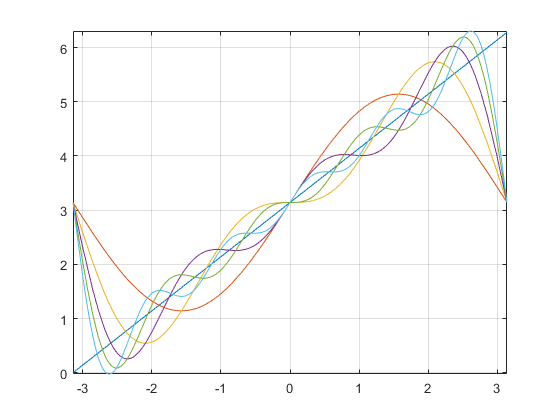

% (2*(-1)^(m + 1)*sin(m*x))/m
abf(m)=af(m)+bf(m);
% (2*(-1)^(m + 1)*sin(m*x))/m

fplot(f(x),[-pi pi]);
hold on;

f1=a0/2;
for m=1:5
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[-pi pi])
    grid on
end
hold off


a0/2

$$ans = \pi$$

%
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & 0 & 2 & 2\,\sin\left(x\right)\\ 2 & 0 & -1 & -\sin\left(2\,x\right)\\ 3 & 0 & \frac{2}{3} & \frac{2\,\sin\left(3\,x\right)}{3}\\ 4 & 0 & -\frac{1}{2} & -\frac{\sin\left(4\,x\right)}{2}\\ 5 & 0 & \frac{2}{5} & \frac{2\,\sin\left(5\,x\right)}{5} \end{array}\right)$$

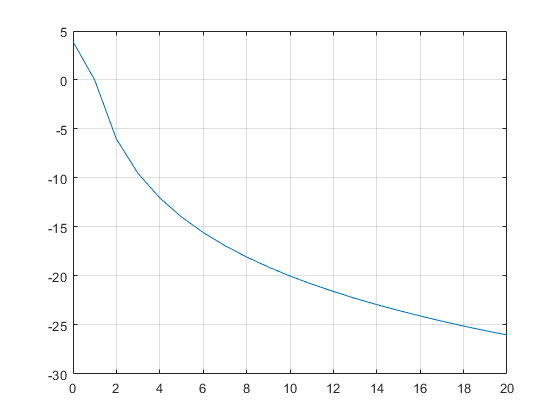

% [ 1, 0,    2,       2*sin(x)]
% [ 2, 0,   -1,      -sin(2*x)]
% [ 3, 0,  2/3, (2*sin(3*x))/3]
% [ 4, 0, -1/2,    -sin(4*x)/2]
% [ 5, 0,  2/5, (2*sin(5*x))/5]

x=0:20;
y(1)=a0/2;
for m=1:20
    y(m+1)=a(m)+1i*b(m);
end
yd=20*log10(abs(y)/abs(y(2)));

plot(x,yd)
grid on;